# Neural Network on fMRI 4 Regions

Lily Jiang (worked with Avery Clowes and Elias Wheatfall)

September 28, 2023

Task: Create your own neural network to analyze the data train4regions data. Pay attention to the dimensions and orientation of the data. You’ll need `t` (the answers) to be numbers instead of categories (see the trainIsFace variable, which is a logical indicator of whether or not the trial is a face (1) or house (0)).

## Configure variables and network

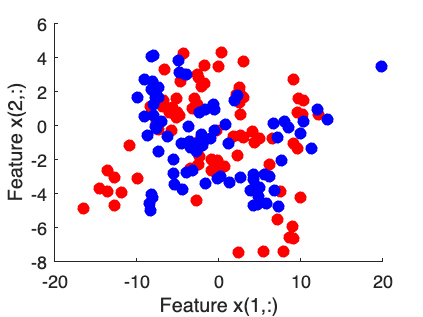

load('fMRI4regionsNN.mat');

t = trainIsFace;
x = train4regions;

% Plot data to get an overview
figure;
hold on;
plot(x(1,t==0),x(2,t==0),'r.','MarkerSize',20);
plot(x(1,t==1),x(2,t==1),'b.','MarkerSize',20);
xlabel('Feature x(1,:)');
ylabel('Feature x(2,:)');
hold off;


trainFcn = 'trainbr';  % trainlm and trainscg
hiddenLayerSize = [3];

net = patternnet(hiddenLayerSize,trainFcn);
net = configure(net,x,t);

% Divide data (note: only need valRatio for trainscg)
net.divideParam.trainRatio = 0.6;
net.divideParam.testRatio = 0.4;

## Train the network using the train data

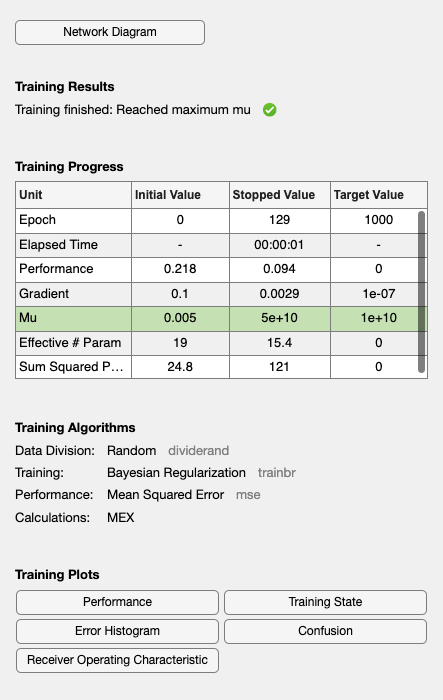

[net,tr] = train(net,x,t);

## Explore the network and the graphs that appear (training plots)

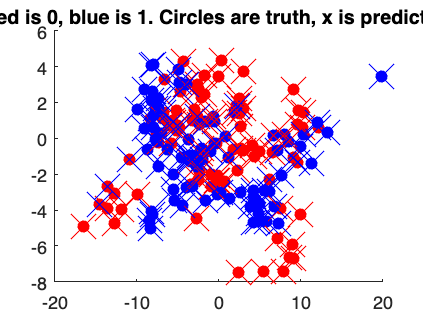

train_x = x;
output_y = net(train_x);
output_binary = double(output_y >= .5);

figure;
hold on;
plot(train_x(1,t==0),train_x(2,t==0),'r.','MarkerSize',20);
plot(train_x(1,t==1),train_x(2,t==1),'b.','MarkerSize',20); 
plot(train_x(1,output_binary==0),train_x(2,output_binary==0),'rx','MarkerSize',20);
plot(train_x(1,output_binary==1),train_x(2,output_binary==1),'bx','MarkerSize',20);
hold off;
title('Red is 0, blue is 1. Circles are truth, x is prediction');

## Calculate the accuracy and confusion matrix for the train data

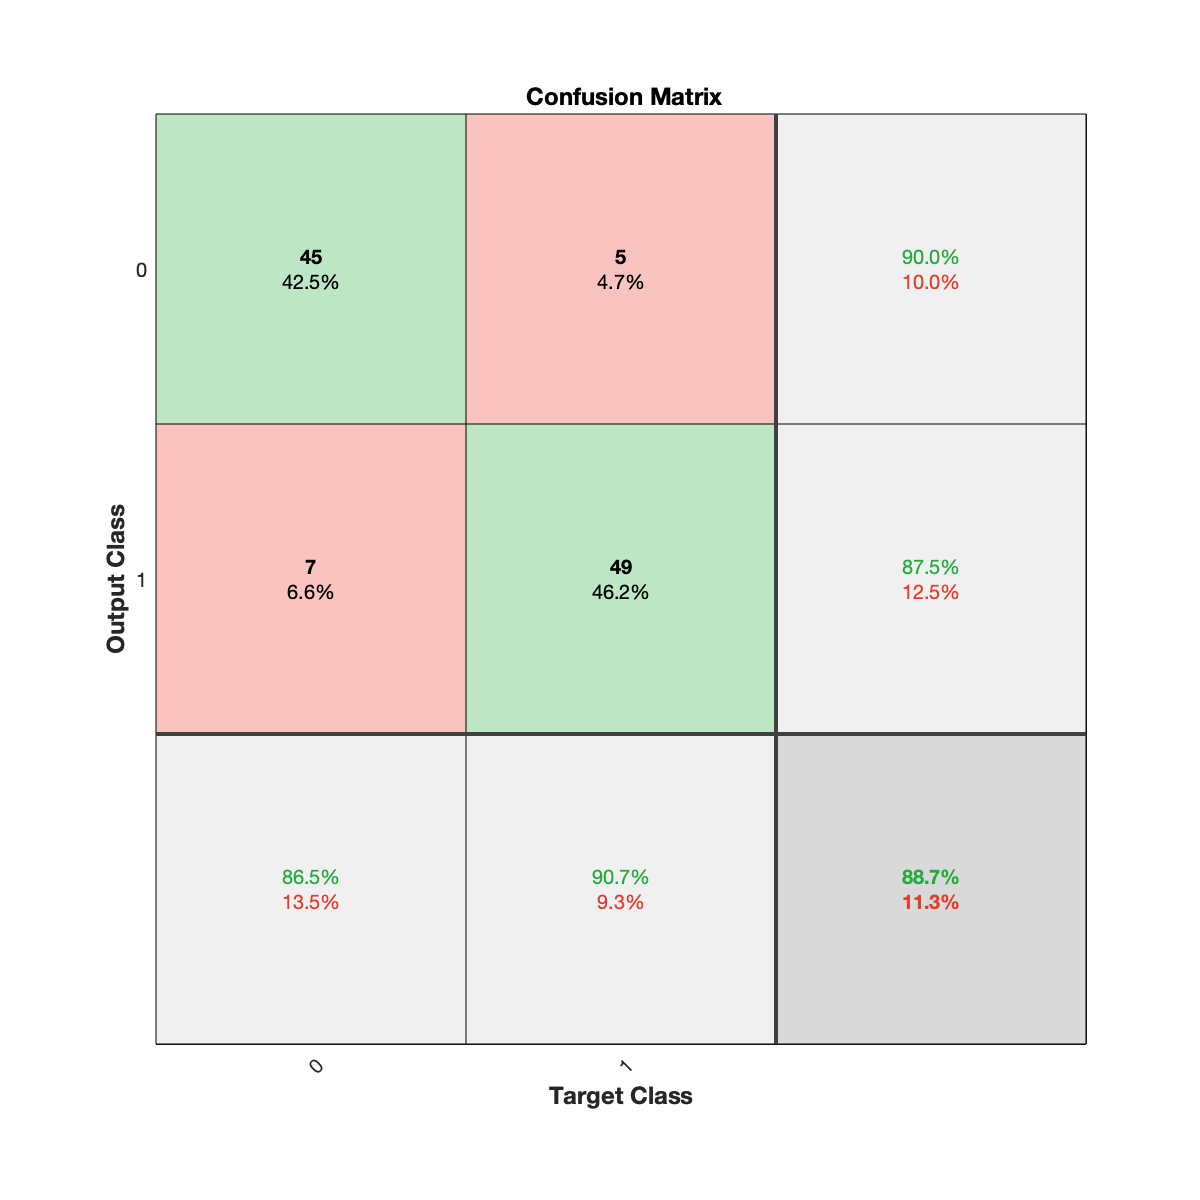

plotconfusion(t(tr.trainInd), output_binary(tr.trainInd));

Accuracy: 84.9%

## Test the network using the test data and calculate the accuracy and confusion matrix

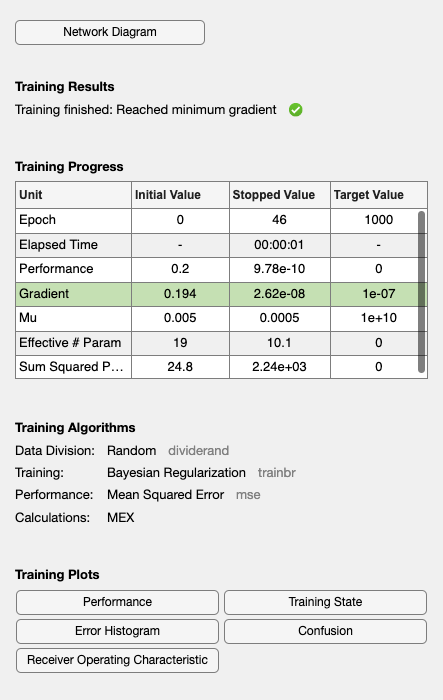

t_test = testIsFace;
x_test = test4regions;

net_test = patternnet(hiddenLayerSize,trainFcn);
net_test = configure(net_test,x_test,t_test);

[net_test,tr_test] = train(net_test,x_test,t_test);


output_y_test = net(x_test);
output_binary_test = double(output_y_test >= .5);

Get the confusion matrix:

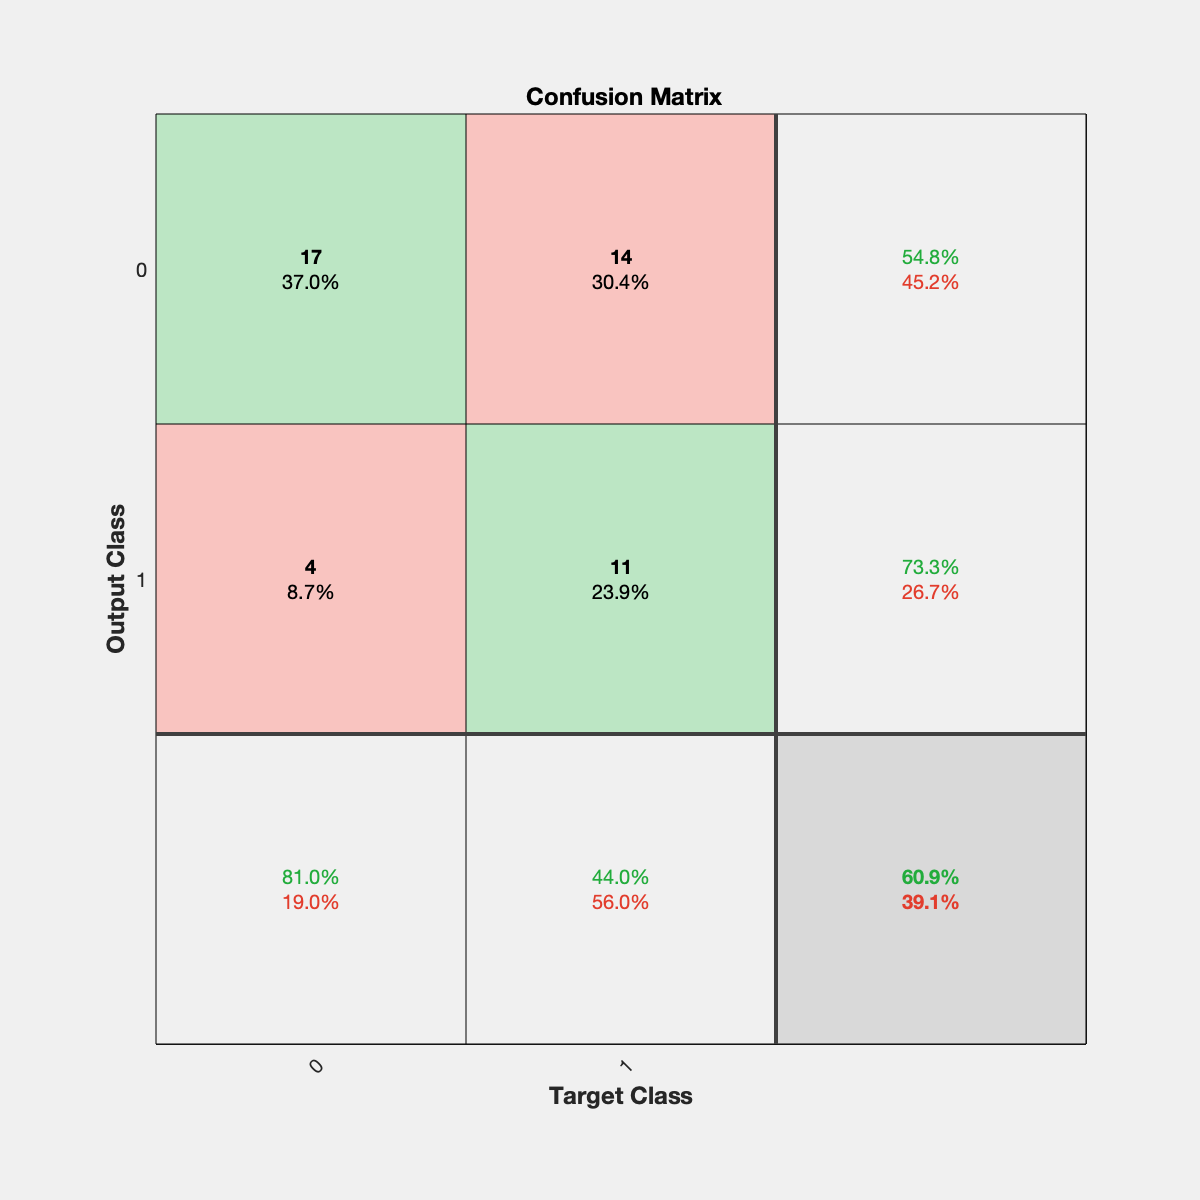

plotconfusion(t_test(tr_test.trainInd), output_binary_test(tr_test.trainInd));

Accuracy: 60.9%